# Image and Video Processing - Task 4

## Motion tracking of feature points and dense optical flow

Daniel Kuknyo [Y80L35]

### Read and setup 

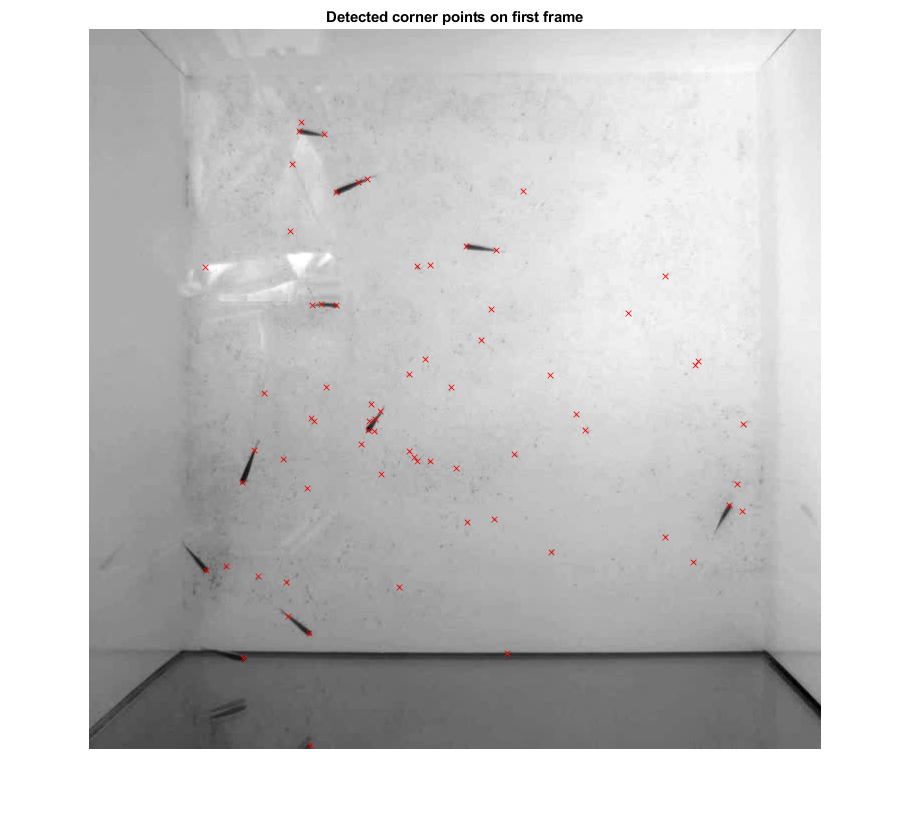

clear all; close all; clc;

% Read input
framerate = 4; 
n_strongest = 70;
max_distance = 4; % default: 4
max_displacement = 2; % default: 2

vname = 'fishes.avi';
video = VideoReader(vname);
videoFrame = readFrame(video);

% Detect points on the video to track
points = detectMinEigenFeatures(rgb2gray(videoFrame));

if(strcmp(vname,'fishes.avi'))
    points = points.selectStrongest(n_strongest);
    max_distance = 32; % default: 4
    max_displacement = 16; % default: 2
end

points = points.Location;

% Visualize points
imshow(videoFrame);
hold on;
for i = 1:size(points, 1)
    px = points(i, 1);
    py = points(i, 2);
    plot(px, py, 'x', 'Color', 'red');
end
title('Detected corner points on first frame');
hold off;

### Initialize tracker, player and writer

videoPlayer = vision.VideoPlayer('Position', [100 100 [size(videoFrame, 2), size(videoFrame, 1)]]);
pointTracker = vision.PointTracker('MaxBidirectionalError', max_displacement);
initialize(pointTracker, points, videoFrame);

oldPoints = points;

writer = VideoWriter(strcat('output_', vname), 'Uncompressed AVI');
writer.FrameRate = framerate;
open(writer);

### Tracking the points

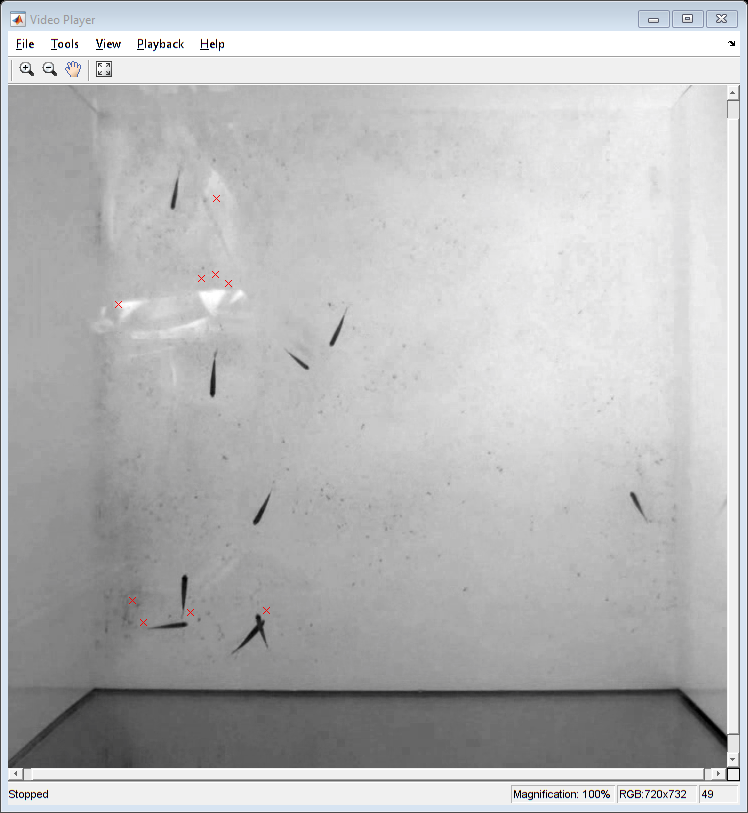

while hasFrame(video)
    vframe = readFrame(video); % Next frame
    [points, isFound] = step(pointTracker, vframe);
    visiblePoints = points(isFound, :);
    oldInliers = oldPoints(isFound, :);
   
    if size(visiblePoints, 1) >= 2 % need at least 2 points
        % Estimate the geometric transformation
        [xform, inlierIdx] = estimateGeometricTransform2D(...
            oldInliers, visiblePoints, 'similarity', 'MaxDistance', max_distance);
        
        oldInliers = oldInliers(inlierIdx, :);
        visiblePoints = visiblePoints(inlierIdx, :);

        % Create frame with markers
        vframe = insertMarker(vframe, visiblePoints, 'x-mark', 'Color', 'red');       
        writeVideo(writer, vframe);

        oldPoints = visiblePoints;
        setPoints(pointTracker, oldPoints);
    end
    
    % Display the annotated video frame using the video player object
    step(videoPlayer, vframe);
end

close(writer);
release(pointTracker);
release(videoPlayer);

### Setting up for optical flow

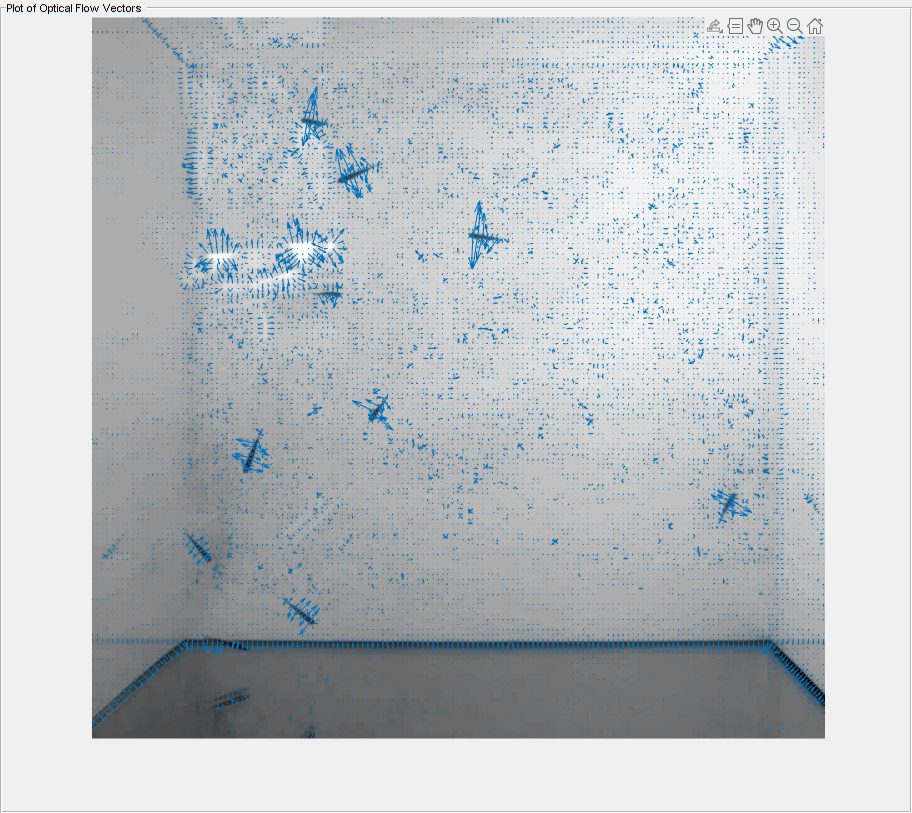

video = VideoReader(vname);
optical_writer = VideoWriter(strcat('output_opticFlow_', vname), 'Uncompressed AVI');
optical_writer.FrameRate = 1;
open(optical_writer);

opticFlow = opticalFlowHS();

h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position', [0 0 1 1], 'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);
i = 1;
while hasFrame(video)
    if(mod(i,4) == 0 || i == 1)
        vframe = readFrame(video);
        gframe = im2gray(vframe);  
        flow = estimateFlow(opticFlow, gframe);
        imshow(vframe)
        
        hold on
        plot(flow, 'DecimationFactor', [5 5], 'ScaleFactor', 60, 'Parent', hPlot);
        hold off
    
        F = getframe(hPlot);
        iframe = frame2im(F);
        writeVideo(optical_writer, iframe);
    end
    
    pause(10^-3)
    i = i + 1;
end

close(optical_writer);
close(videoPlayer);

close all;